`Task 2: Overview`

This livescript is meant to give an overview of the functions and results that are already implemented. First we have sample possibilities for the two models

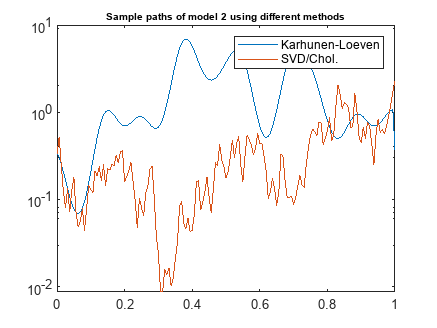

% Discretization of random field
N = 20;

% Discretization of FEM
l = 3;
I = N*2^l;

% Discretization of the FEM
x = linspace(0, 1, I+1);

% Parameters
sigma = 0.5; % Model 1
nu = 0.5; % Model 2


% Model 1
sample_model1 = a_constant_coeff(x, N, sigma);

% Model 2 using SVD/Cholesky
sample_decomp = a_matern(x, nu);

% Model 2 using KL expansion
sample_KL = a_KL_expansion(x, nu, N);

% Model 2 using Fourier expansion
% TODO

% Plot of samples
semilogy(x, sample_KL, x, sample_decomp)
legend('Karhunen-Loeven', 'SVD/Chol.')
title("Sample paths of model 2 using different methods", fontsize=8)

Now using these methods to sample the random field $a(x,w)$ we can approximate the PDE using FEM

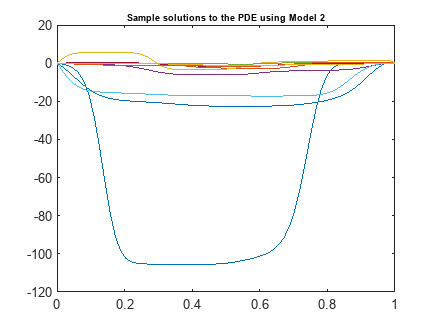

I = 64;
h = 1/I;
x = linspace(0, 1, I+1);
%rng(1)
for k=1:10
    u_h = FEM_KL(I, 2);
    plot(x, u_h);
    title("Sample solutions to the PDE using Model 2", fontsize=7)
    hold on;
end

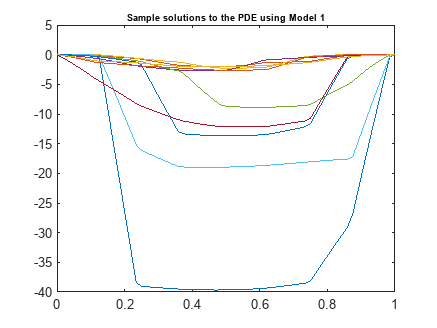


figure()
for k=1:10
    u_h = FEM_KL(I, 1);
    plot(x, u_h);
    title("Sample solutions to the PDE using Model 1", fontsize=7)
    hold on;
end

Now we can estimate our QoI using Monte Carlo

clc
tic
M = 10000;
c_alpha = 1.96;

ref_sol_model1 = -2.88288648447669;
ref_var_model1 = 9.29186430773522;

ref_sol_model2 = -5.22615137597944;
ref_var_model2 = 235.267533305701;

samples_M1 = zeros([1 M]);
samples_M2 = zeros([1 M]);
MC_est_M1 = zeros([1 M]);
MC_est_M2 = zeros([1 M]);
MC_var_M1 = zeros([1 M]);
MC_var_M2 = zeros([1 M]);
CLT_M1 = zeros([1 M]);
CLT_M2 = zeros([1 M]);
err_M1 = zeros([1 M]);
err_M2 = zeros([1 M]);
coeff_of_var_M1 = zeros([1 M]);
coeff_of_var_M2 = zeros([1 M]);

for k=progress(1:M)
    samples_M1(k) = QoI(I, 1);
    samples_M2(k) = QoI(I, 2);
    MC_est_M1(k) = 1/k*sum(samples_M1(1:k));
    MC_est_M2(k) = 1/k*sum(samples_M2(1:k));
    if k>1
        MC_var_M1(k) = (1/(k-1))*sum((samples_M1(1:k) - MC_est_M1(k)).^2);
        MC_var_M2(k) = (1/(k-1))*sum((samples_M2(1:k) - MC_est_M2(k)).^2);
    end
    coeff_of_var_M1(k) = sqrt(MC_var_M1(k))/MC_est_M1(k);
    coeff_of_var_M2(k) = sqrt(MC_var_M2(k))/MC_est_M2(k);
end

Processing:  000%  |                                  | 0/10000it [00:00:00<Inf:NaN:NaN, Inf it/s]


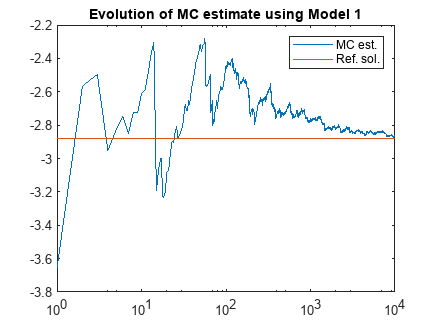


for i=1:M
    CLT_M1(i) = (c_alpha*sqrt(ref_var_model1))/(sqrt(i)*abs(ref_sol_model1));
    CLT_M2(i) = (c_alpha*sqrt(ref_var_model2))/(sqrt(i)*abs(ref_sol_model2));
    err_M1(i) = abs(MC_est_M1(i) - ref_sol_model1)/abs(ref_sol_model1);
    err_M2(i) = abs(MC_est_M2(i) - ref_sol_model2)/abs(ref_sol_model2);
end

figure()
semilogx(1:M, MC_est_M1, 1:M, ref_sol_model1*ones([1 M]));
legend("MC est.", "Ref. sol.")
title("Evolution of MC estimate using Model 1")

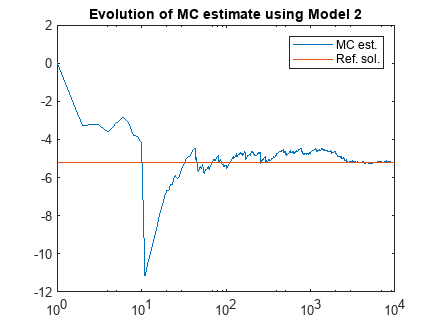

figure()
semilogx(1:M, MC_est_M2, 1:M, ref_sol_model2*ones([1 M]));
legend("MC est.", "Ref. sol.")
title("Evolution of MC estimate using Model 2")

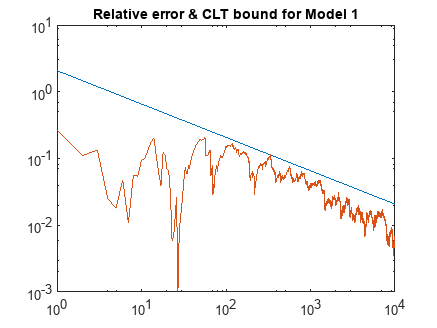


figure()
loglog(1:M, CLT_M1, 1:M, err_M1)
title("Relative error & CLT bound for Model 1")
savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "HW1_Part2_MC_1")

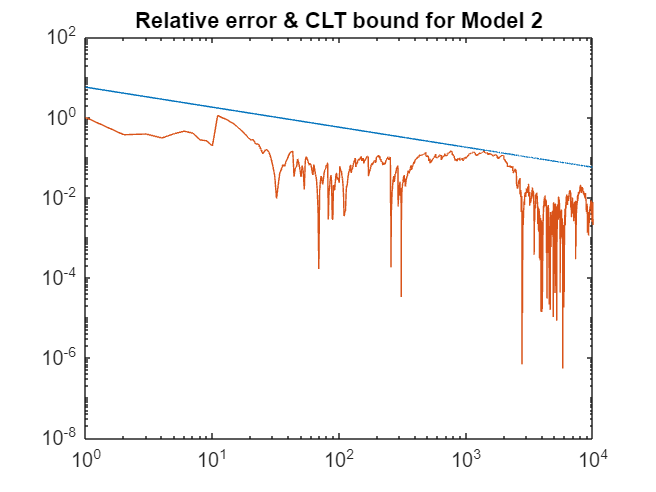

figure()
loglog(1:M, CLT_M2, 1:M, err_M2)
title("Relative error & CLT bound for Model 2")
savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "HW1_Part2_MC_2")

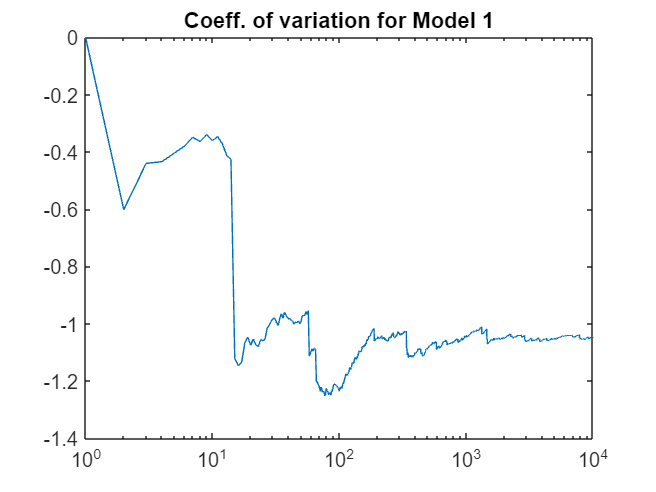


figure()
semilogx(1:M, coeff_of_var_M1);
title("Coeff. of variation for Model 1")
savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "HW1_Part2_CoV_1")

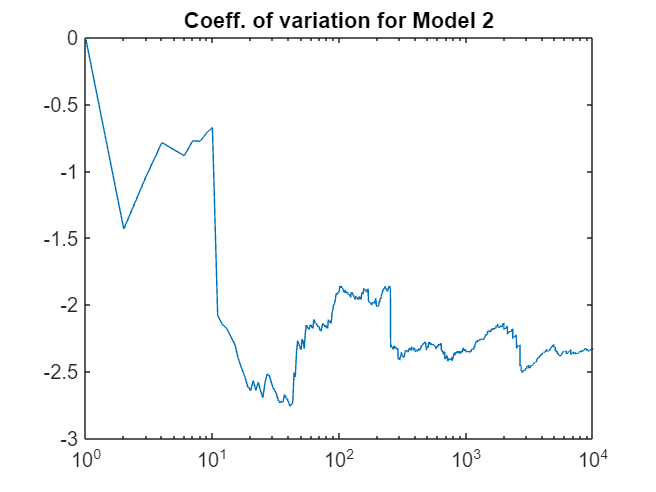


figure()
semilogx(1:M, coeff_of_var_M2);
title("Coeff. of variation for Model 2")
savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "HW1_Part2_CoV_2")



toc

Elapsed time is 34.674694 seconds.
